# Timing Error Detector S-Curves

This script demonstrates the S-curves corresponding to the timing error detector (TED) methods described in Michael Rice's book (Section 8.4.1). For each TED method, this script shows the S-curve for a fixed roll-off factor obtained both analytically and through simulation. Furthermore, this script shows the analytic TED gain Kp for varying roll-off factors. In all cases, this script focuses on the data-aided operation, while leaving the decision-directed operation for future work. The exception is the Gardner TED, which is always purely non-data-aided.

rolloff = 0.5;
plotSCurve = 1;

## Maximum Likelihood Timing Error Detector (MLTED)

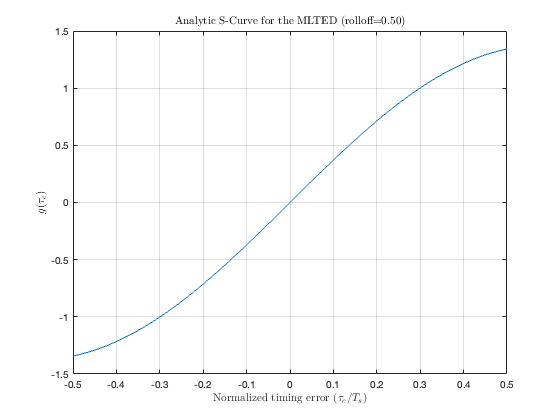

Kp_analytic_ml = 3.7572

Kp_analytic_ml = calcTedKp('MLTED', rolloff, 'analytic', plotSCurve)

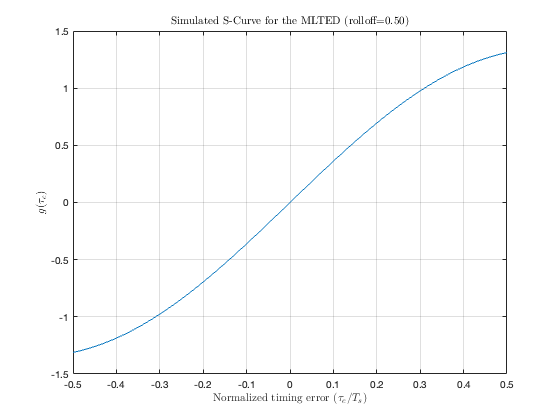

Kp_simulated_ml = 3.6594

Kp_simulated_ml = calcTedKp('MLTED', rolloff, 'simulated', plotSCurve)

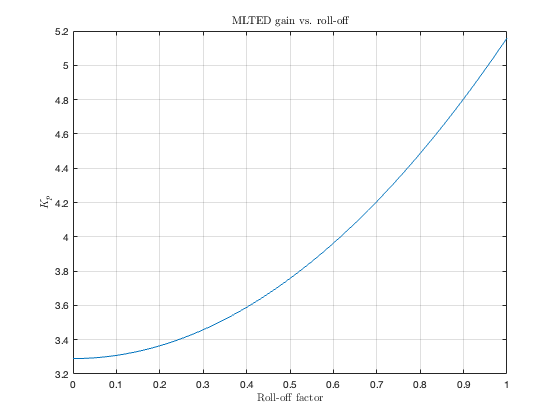

plotTedGain('MLTED')

**Note:** the above function matches in shape relative to Fig. 8.4.4 but not in terms of the actual scaling. The difference likely has something to do with how the author computes the dMF using the first central difference according to Eq. (3.61). The latter equation involves knowledge of the sampling period, i.e., divides by $2T$. In contrast, here we compute the first central difference over two normalized sample intervals of $1/L$ each, i.e., we divide by $2/L$.

## Early–Late Timing Error Detector (ELTED)

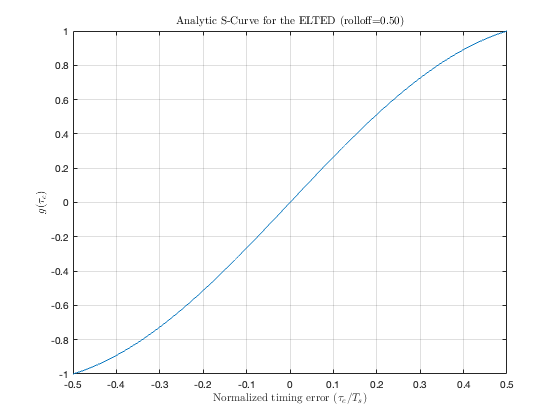

Kp_analytic_el = 2.6859

Kp_analytic_el = calcTedKp('ELTED', rolloff, 'analytic', plotSCurve)

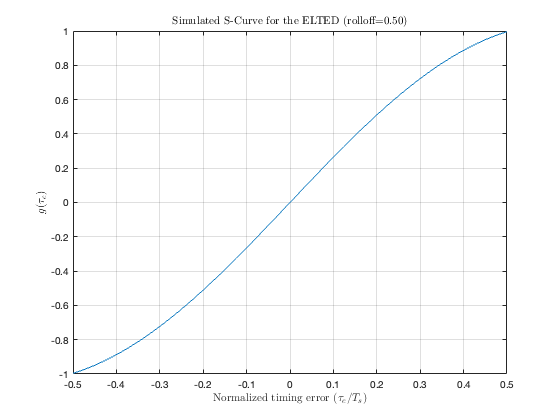

Kp_simulated_el = 2.6718

Kp_simulated_el = calcTedKp('ELTED', rolloff, 'simulated', plotSCurve)

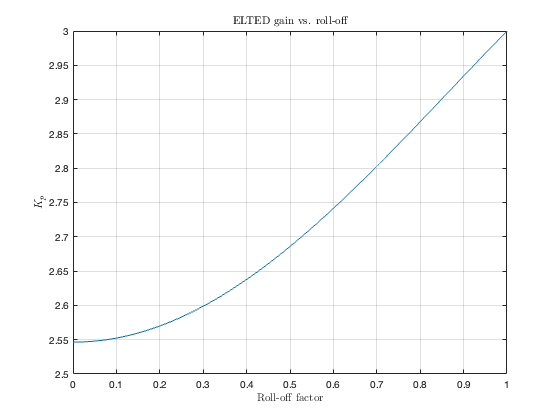

plotTedGain('ELTED')

## Zero-Crossing Timing Error Detector (ZCTED)

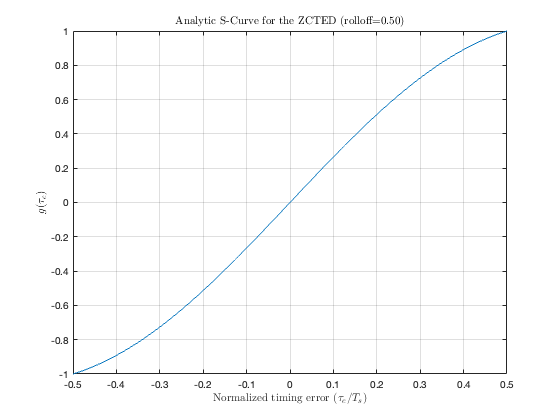

Kp_analytic_zc = 2.6859

Kp_analytic_zc = calcTedKp('ZCTED', rolloff, 'analytic', plotSCurve)

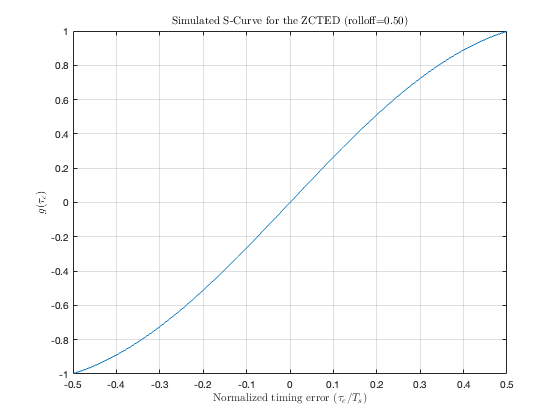

Kp_simulated_zc = 2.6762

Kp_simulated_zc = calcTedKp('ZCTED', rolloff, 'simulated', plotSCurve)

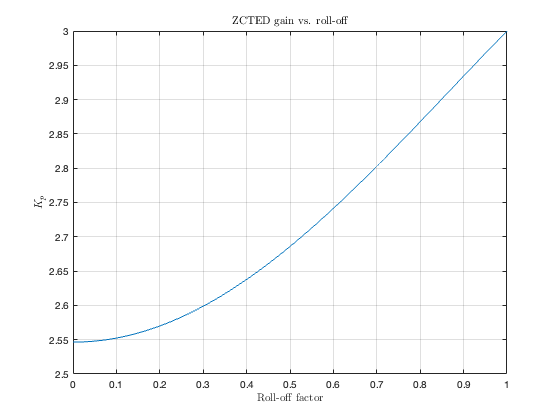

plotTedGain('ZCTED')

## Gardner Timing Error Detector

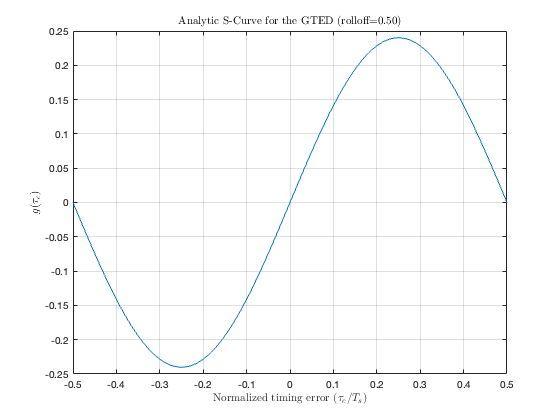

Kp_analytic_g = 1.5085

Kp_analytic_g = calcTedKp('GTED', rolloff, 'analytic', plotSCurve)

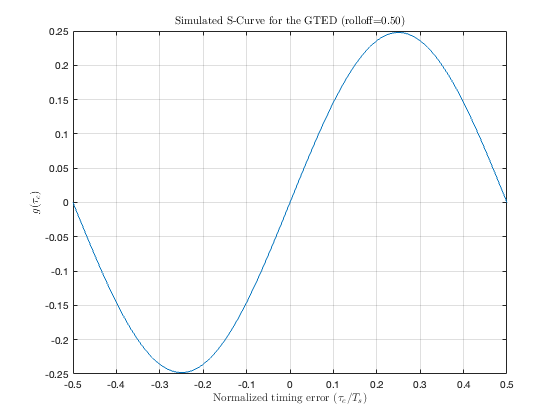

Kp_simulated_g = 1.5573

Kp_simulated_g = calcTedKp('GTED', rolloff, 'simulated', plotSCurve)

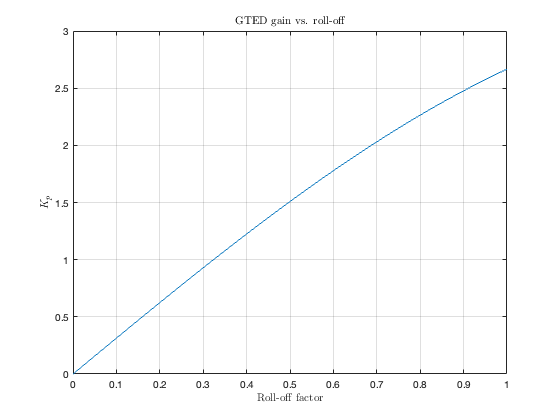

plotTedGain('GTED')

**Note: **The S-curves shown above are scaled differently than Fig. 8.4.9. The difference is likely due to Michael Rice's scaling based on Ts. Here, again, we ignore any knowledge of symbol/sample rates. For example, our original timing error metric is in units of sample periods and the normalized error is the original divided by the oversampling factor $L$. The normalized result should be equivalent to Rice's $\tau_e$ in units of time normalized by $T_s$ (symbol period), also in units of time. However, the closed-form expression in Eq. (8.45) changes in terms of normalization. See the notes in the implementation of function `calcSCurve()`. In any case, this problem applies only to the GTED and arises indirectly in the MLTED case. The closed-form gain expressions of the other TEDs are independent of $T_s$.

## Mueller and Müller Timing Error Detector (MMTED)

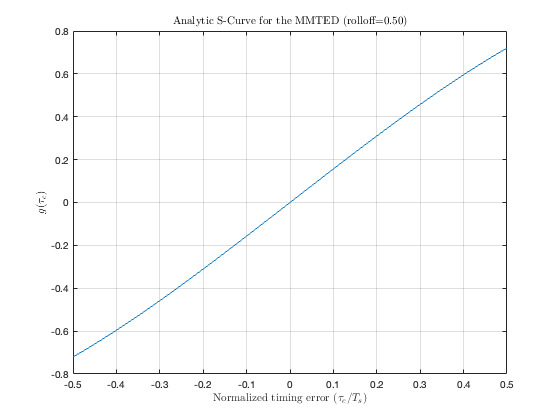

Kp_analytic_mm = 1.5708

Kp_analytic_mm = calcTedKp('MMTED', rolloff, 'analytic', plotSCurve)

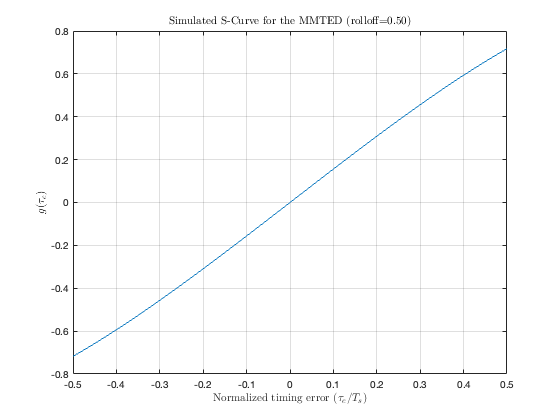

Kp_simulated_mm = 1.5653

Kp_simulated_mm = calcTedKp('MMTED', rolloff, 'simulated', plotSCurve)

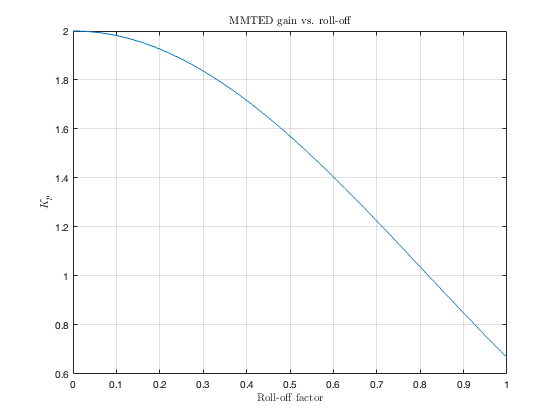

plotTedGain('MMTED')